# Torsión en barras con perfiles cuadriculados

clc
clear all %#ok<*CLALL>

mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
[pathstr,~,~] = fileparts(mfilePath);
cd(pathstr)

PYTHON_EXEC="python.exe";
profiles_dir = "perfiles";
profile_files = get_profile_files(profiles_dir);

% Para MATLAB (R2022b) New Desktop Plugin 
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue= 'light';
 

**Crear nuevo perfil**

new_profile_name = "";
ncells = 10;
if ~exist(profiles_dir, 'dir')
   mkdir(profiles_dir)
end
output = sprintf("%s/%s", profiles_dir, new_profile_name);
system(sprintf("%s profile_designer.py %s %d", PYTHON_EXEC, output, ncells));
if ~contains(profile_files, new_profile_name)
    profile_files(end+1) = sprintf("%s.pbm", new_profile_name);
end
 

**Seleccionar perfil**

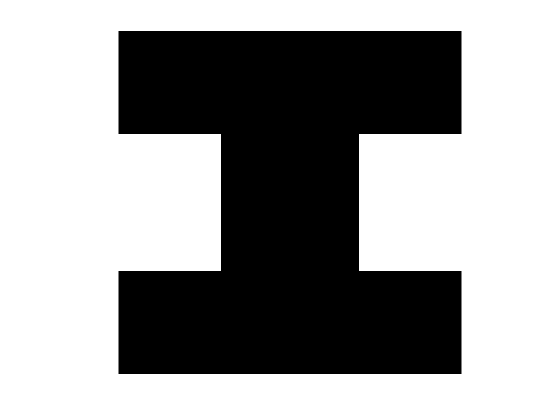

profile_name = "i";
profile_ext = "pbm";
profile_file = sprintf("%s/%s.%s", profiles_dir, profile_name, profile_ext);
profile_data = imread(profile_file) > 0;
imshow(imresize(profile_data, 5, "nearest"))

**Parámetros**

params = struct();
params.T = 4500; % torque [N*mm]
params.W = 10; % ancho perfil [mm]
params.L = 100; % longitud perfil [mm]
params.G = 80e3; % modulo de rigidez cortante material [MPa]
params.sy = 205; % esfuerzo de fluencia [MPa]
params.h = 0.05; % (dx) tamaño de malla [mm]
 

**Solucionar sistema**

 
ts = torsionsys(~profile_data, params);
tic
ts = ts.setupsystem();
tset = toc;
tic
ts = ts.solvesystem();
tsol = toc;
ts = ts.arrangesolution();

disp("¡Hecho!")

¡Hecho!


disp(params)

     T: 4500
     W: 10
     L: 100
     G: 80000
    sy: 205
     h: 0.0500



disp("Resultados")

Resultados


fprintf("Tiempo creación sistema:      %0.3f segs\n", tset)

Tiempo creación sistema:      3.093 segs


fprintf("Tiempo solución sistema:      %0.3f segs\n", tsol)

Tiempo solución sistema:      1.896 segs


fprintf("Momento polar de inercia (J): %0.3f mm^4\n", ts.J)

Momento polar de inercia (J): 1322.730 mm^4


fprintf("Máximo esfuerzo cortante:     %0.3f MPa\n", ts.tauMax)

Máximo esfuerzo cortante:     123.320 MPa


fprintf("Factor de seguridad:          %0.3f\n", ts.ny)

Factor de seguridad:          0.831


fprintf("Deformación por longitud:     %0.2e rads/mm (%0.4f°/mm)\n", ts.theta, rad2deg(ts.theta))

Deformación por longitud:     4.43e-07 rads/mm (0.0000°/mm)


fprintf("Ángulo de deformación total:  %0.2e rads (%0.4f°)\n", ts.gamma, rad2deg(ts.gamma))

Ángulo de deformación total:  4.43e-05 rads (0.0025°)


**Gráficas sección**

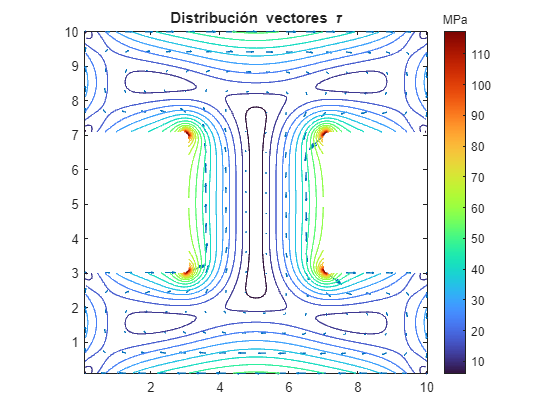

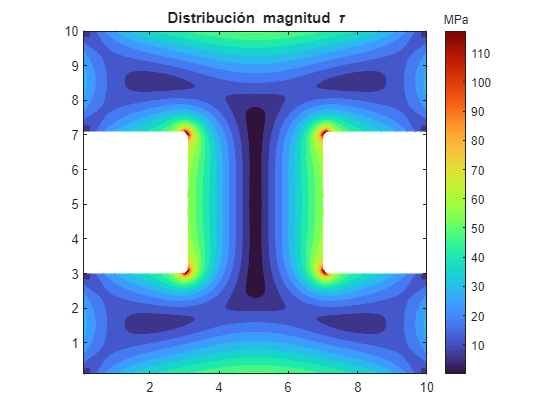

showtau = true;
showtauxy = true;
showPhi = true;
 

if ~(showtau || showtauxy || showPhi)
    disp("Gráficas distribución deshabilitadas") %#ok<*UNRCH>
end
if showtau
    ts.showtaucamp();
    ts.showtau();
end

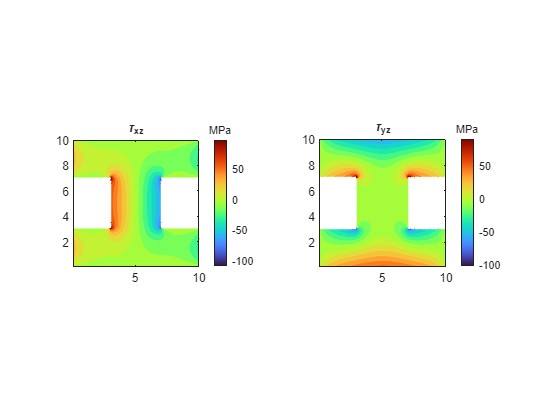

if showtauxy
    ts.showtaucomps();
    %ts.showtauxz()
    %ts.showtauyz()
end

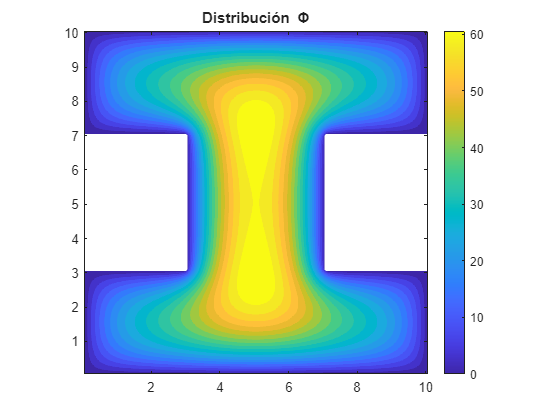

if showPhi
    ts.showPhi()
end

function profile_files = get_profile_files(profiles_dir)
    profile_files = struct2cell(dir(sprintf("%s/*.ppm",profiles_dir)));
    profile_files = string(profile_files(1,:));
end